# Midterm 2

Created By: Edward Chang (ecc567)

Date: 7/26/2023

## Question 1a - Response

**3-Dimensional Poisson Problem Derivation**

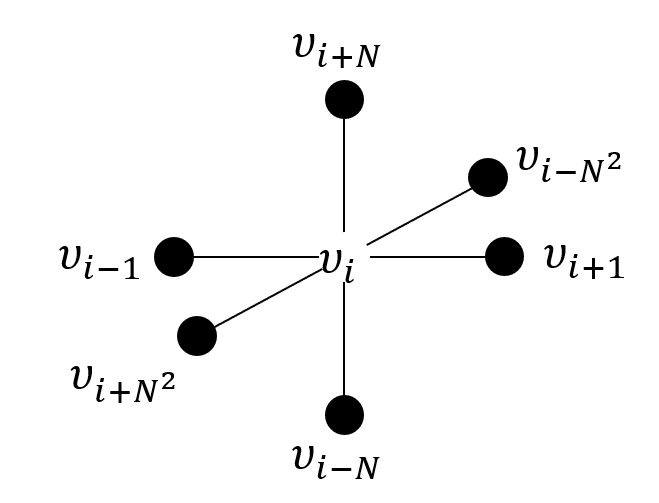

Let $\phi_i$ be the value of f(x,y) at the mesh point $i$.  One can approximate


$$\begin{array}{l}
x-\textrm{dimension}:\;\frac{\partial^2 u\left(x,y,z\right)}{\partial x^2 }\approx \frac{u\left(x-h,y,z\right)-2u\left(x,y,z\right)+u\left(x+h,y,z\right)}{h^2 }\\
y-\textrm{dimension}:\;\frac{\partial^2 u\left(x,y,z\right)}{\partial y^2 }\approx \frac{u\left(x,y-h,z\right)-2u\left(x,y,z\right)+u\left(x,y+h,z\right)}{h^2 }\\
z-\textrm{dimension}:\;\frac{\partial^2 u\left(x,y,z\right)}{\partial z^2 }\approx \frac{u\left(x,y,z-h\right)-2u\left(x,y,z\right)+u\left(x,y,z+h\right)}{h^2 }
\end{array}$$


so that


$$-\frac{\partial^2 u}{{\partial x}^2 }-\frac{\partial^2 u}{{\partial y}^2 }-\frac{\partial^2 u}{{\partial z}^2 }=f\left(x,y,z\right)$$


becomes


$$\begin{array}{l}
\frac{-u\left(x-h,y,z\right)+2u\left(x,y,z\right)-u\left(x+h,y,z\right)}{h^2 }+\frac{-u\left(x,y-h,z\right)+2u\left(x,y,z\right)-u\left(x,y+h,z\right)}{h^2 }+\\
\frac{-u\left(x,y,z-h\right)+2u\left(x,y,z\right)-u\left(x,y,z+h\right)}{h^2 }=f\left(x,y,z\right)
\end{array}$$


or, equivalently,


$$\frac{-u\left(x-h,y,z\right)-u\left(x,y-h,z\right)-u\left(x,y,z-h\right)+6u\left(x,y,z\right)-u\left(x+h,y,z\right)-u\left(x,y+h,z\right)-u\left(x,y,z+h\right)}{h^2 }=f\left(x,y,z\right)$$


If $\left(x,y,z\right)$ corresponds to the point $i$ in a mesh where the interior points form an N x N x N grid cube, this translates to the system of linear equations


$$-\upsilon_{i-N^2 } -\upsilon_{i-N} -\upsilon_{i-1} +6\upsilon_i -\upsilon_{i+1} -\upsilon_{i+N} -\upsilon_{i+N^2 } =h^2 \phi_i$$


This can be rewritten as


$$\upsilon_i =\frac{h^2 \phi +\upsilon_{i-N^2 } +\upsilon_{i-N} +\upsilon_{i-1} +\upsilon_{i+1} +\upsilon_{i+N} +\upsilon_{i+N^2 } }{6}$$


**Rephrase As Solving **$\mathit{\mathbf{A}}\upsilon ={\mathit{\mathbf{h}}}^2 \phi$

All this insights can be put together into a systems of linear equations where $\phi_i =f\left(\chi_i ,\psi_j ,\zeta_k \right)\;$if $\left(\chi_i ,\psi_j ,\zeta_k \right)$ is the point assoicated with the value $\upsilon_i$.  In matrix notation this becomes:$A\upsilon =h^2 \phi$.  The figure below visually describes the matrix notation for a mesh (3-dimensional) cube of 3 x 3 x 3, with 27 interior points.

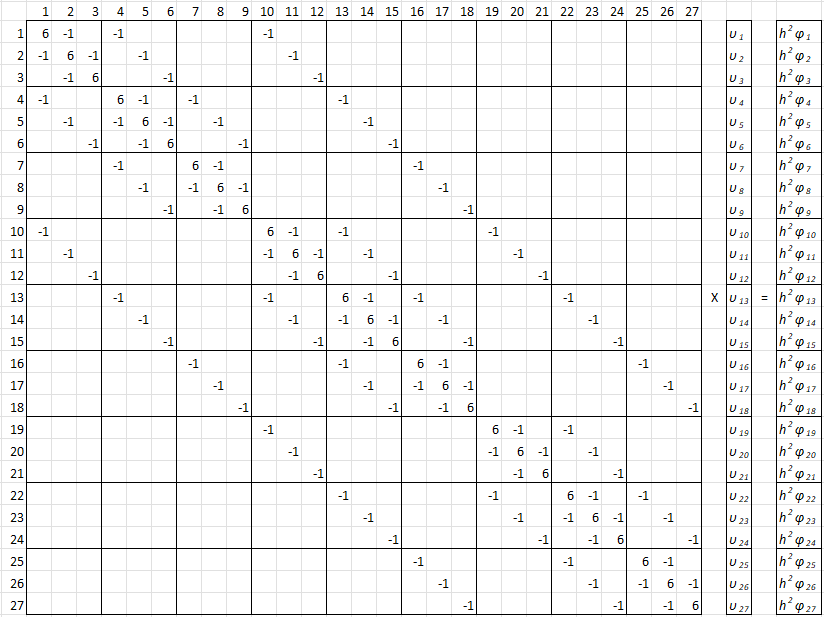

**Describe The Sparsity Pattern of the Matrix A for 3-Dimensions**

Comparing the above figure in the previous section to a mesh (2-dimensional) grid:

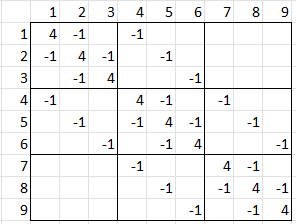

We can see the $A$ matrix has increase in size ($N^3$ x $N^3$) to account for the N x N x N (or $\left.N^3 \right)$ interior mesh points of a mesh cube.  We also see an extra band of -1 coefficients in the upper and lower triangular parts of the matrix, which represent the extra dimension in the negative and positive directions of the 7-point stencil: $-\upsilon_{i-N^2 }$ and $-\upsilon_{i+N^2 }$.  We can also see more sparsity when the interior mesh points' borders a boundary, so one-two points of the 7-point stencil sits on the boundary.  See the figure below for a visual example and pattern.

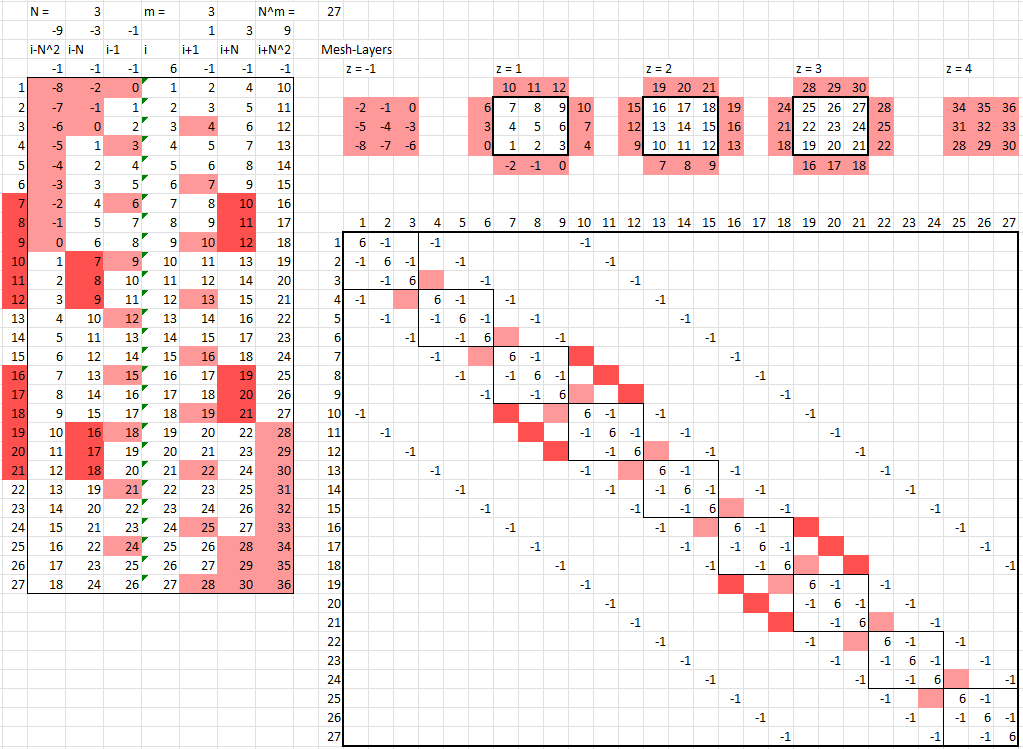

## Question 1b - Response

**Educated Guess for discretizing Poisson Problem in an arbitrary, m**

The A matrix will have m numbers of sub and super diagonals (below and above the main diagonal).  The main diagonal will be amplified and take on the value of $2*m$ as per working out the math in the section above.  Additional sparsity will be created based on interior points impacted by edges / boundaries.  If I have 4-dimension stencil, I will observe more sparsity spread across the 1-dimension diagonals, then less but longer bands of sparsity in the 2-dimension diagonals, and again get less, but longer bands of sparsity in the 3-dimension diagonals.  The 4-dimension diagonals will have no sparse bands in its diagonals, because the boundary impacts exist outside of matrix A.  Looking closer at the length of the gaps in each dimension we can see it follows a pattern of $N^{\textrm{power}}$.  1-dimension diagonal gap length is $N^0 =1$, 2-dimension diagonal gap length is $N^2$... and this pattern continues up to the $m-1$ dimension.  We can identify the intersection of ( $i-N^{\textrm{power}}$ and $i+N^{\textrm{power}}$ ) per dimension by doing remainder division ( $\textrm{mod}\left(i,N^{\textrm{power}} \;\right)$ ).  

See my Create_mdiml_Poisson_problem_nzA() implement for more information.

- Creates the sparse format of the matrix corresponding to the left hand side matrix, A, in the discretized Poisson problem, $A\upsilon =h^2 \phi$, in dimension $m\;\ge \;1$with $N^m$

- Work for any positive integer, $m$, not just $m$ = 1, 2, and 3.

**Sample outputs of Create_mdiml_Poisson_problem_nzA()**

% Sample #1
N = 2;
m = 1;
[ nzA, ir, ic ] = Create_mdiml_Poisson_problem_nzA( N, m );
fprintf( "N = %d, m = %d", N, m );

N = 2, m = 1

A = Generate_A_From_CRS( nzA, ir, ic )

A =      2    -1
    -1     2


% Sample #2
N = 2;
m = 2;
[ nzA, ir, ic ] = Create_mdiml_Poisson_problem_nzA( N, m );
fprintf( "N = %d, m = %d", N, m );

N = 2, m = 2

A = Generate_A_From_CRS( nzA, ir, ic )

A =      4    -1    -1     0
    -1     4     0    -1
    -1     0     4    -1
     0    -1    -1     4


% Sample #3
N = 2;
m = 3;
[ nzA, ir, ic ] = Create_mdiml_Poisson_problem_nzA( N, m );
fprintf( "N = %d, m = %d", N, m );

N = 2, m = 3

A = Generate_A_From_CRS( nzA, ir, ic )

A =      6    -1    -1     0    -1     0     0     0
    -1     6     0    -1     0    -1     0     0
    -1     0     6    -1     0     0    -1     0
     0    -1    -1     6     0     0     0    -1
    -1     0     0     0     6    -1    -1     0
     0    -1     0     0    -1     6     0    -1
     0     0    -1     0    -1     0     6    -1
     0     0     0    -1     0    -1    -1     6


% Sample #4
N = 2;
m = 4;
[ nzA, ir, ic ] = Create_mdiml_Poisson_problem_nzA( N, m );
fprintf( "N = %d, m = %d", N, m );

N = 2, m = 4

A = Generate_A_From_CRS( nzA, ir, ic )

A =      8    -1    -1     0    -1     0     0     0    -1     0     0     0     0     0     0     0
    -1     8     0    -1     0    -1     0     0     0    -1     0     0     0     0     0     0
    -1     0     8    -1     0     0    -1     0     0     0    -1     0     0     0     0     0
     0    -1    -1     8     0     0     0    -1     0     0     0    -1     0     0     0     0
    -1     0     0     0     8    -1    -1     0     0     0     0     0    -1     0     0     0
     0    -1     0     0    -1     8     0    -1     0     0     0     0     0    -1     0     0
     0     0    -1     0    -1     0     8    -1     0     0     0     0     0     0    -1     0
     0     0     0    -1     0    -1    -1     8     0     0     0     0     0     0     0    -1
    -1     0     0     0     0     0     0     0     8    -1    -1     0    -1     0     0     0
     0    -1     0     0     0     0     0     0    -1     8     0    -1     0    -1     0     0


% Sample #5
N = 3;
m = 1;
[ nzA, ir, ic ] = Create_mdiml_Poisson_problem_nzA( N, m );
fprintf( "N = %d, m = %d", N, m );

N = 3, m = 1

A = Generate_A_From_CRS( nzA, ir, ic )

A =      2    -1     0
    -1     2    -1
     0    -1     2


% Sample #6
N = 3;
m = 2;
[ nzA, ir, ic ] = Create_mdiml_Poisson_problem_nzA( N, m );
fprintf( "N = %d, m = %d", N, m );

N = 3, m = 2

A = Generate_A_From_CRS( nzA, ir, ic )

A =      4    -1     0    -1     0     0     0     0     0
    -1     4    -1     0    -1     0     0     0     0
     0    -1     4     0     0    -1     0     0     0
    -1     0     0     4    -1     0    -1     0     0
     0    -1     0    -1     4    -1     0    -1     0
     0     0    -1     0    -1     4     0     0    -1
     0     0     0    -1     0     0     4    -1     0
     0     0     0     0    -1     0    -1     4    -1
     0     0     0     0     0    -1     0    -1     4


## Question 1b - Large A Reviews

Used the code below to try different variation of dimensions to validate my guess on the sparsity pattern.

% Sample #1
N = 2;
m = 5;
[ nzA, ir, ic ] = Create_mdiml_Poisson_problem_nzA( N, m );
A = Generate_A_From_CRS( nzA, ir, ic );
writematrix( A, "data_N" + N + "_m" + m + ".csv" );

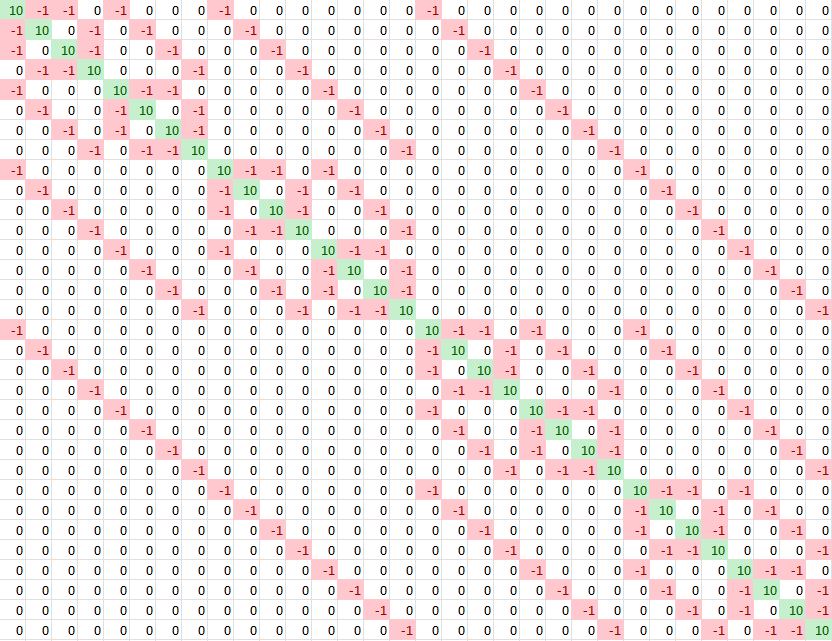

% Sample #2
N = 2;
m = 6;
[ nzA, ir, ic ] = Create_mdiml_Poisson_problem_nzA( N, m );
A = Generate_A_From_CRS( nzA, ir, ic );
writematrix( A, "data_N" + N + "_m" + m + ".csv" );

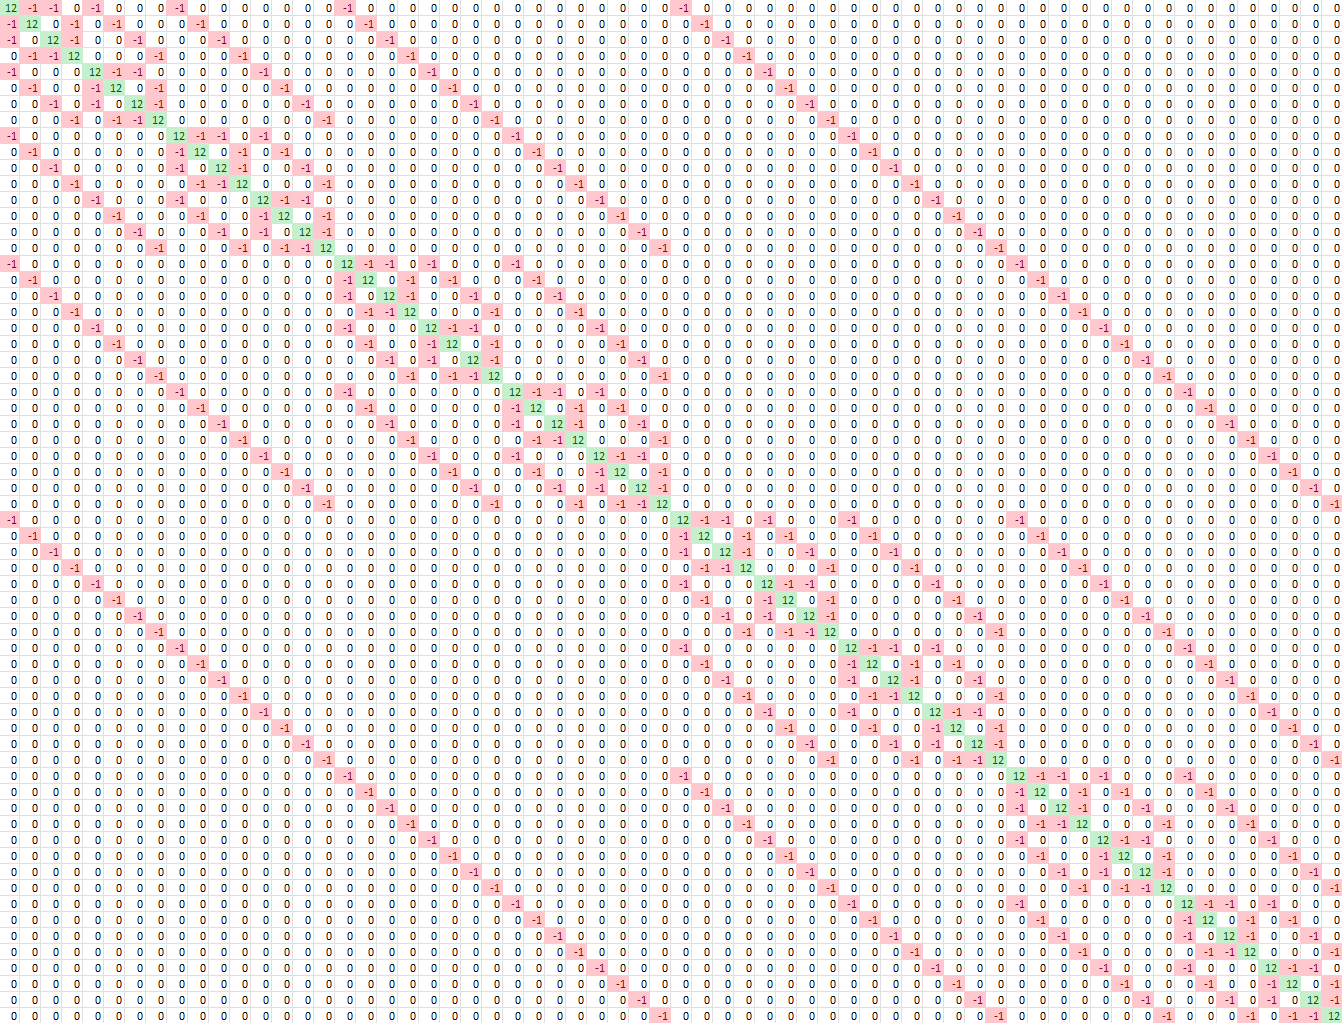

% Sample #3
N = 3;
m = 3;
[ nzA, ir, ic ] = Create_mdiml_Poisson_problem_nzA( N, m );
A = Generate_A_From_CRS( nzA, ir, ic );
writematrix( A, "data_N" + N + "_m" + m + ".csv" );

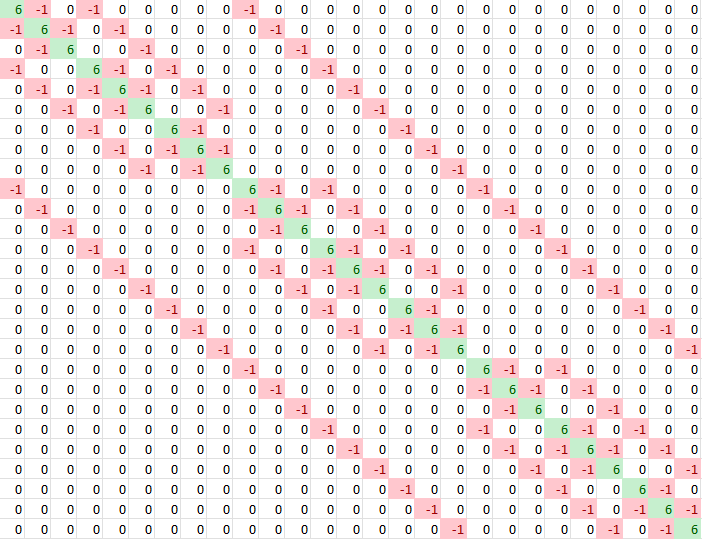

% Sample #4
N = 3;
m = 4;
[ nzA, ir, ic ] = Create_mdiml_Poisson_problem_nzA( N, m );
A = Generate_A_From_CRS( nzA, ir, ic );
writematrix( A, "data_N" + N + "_m" + m + ".csv" );

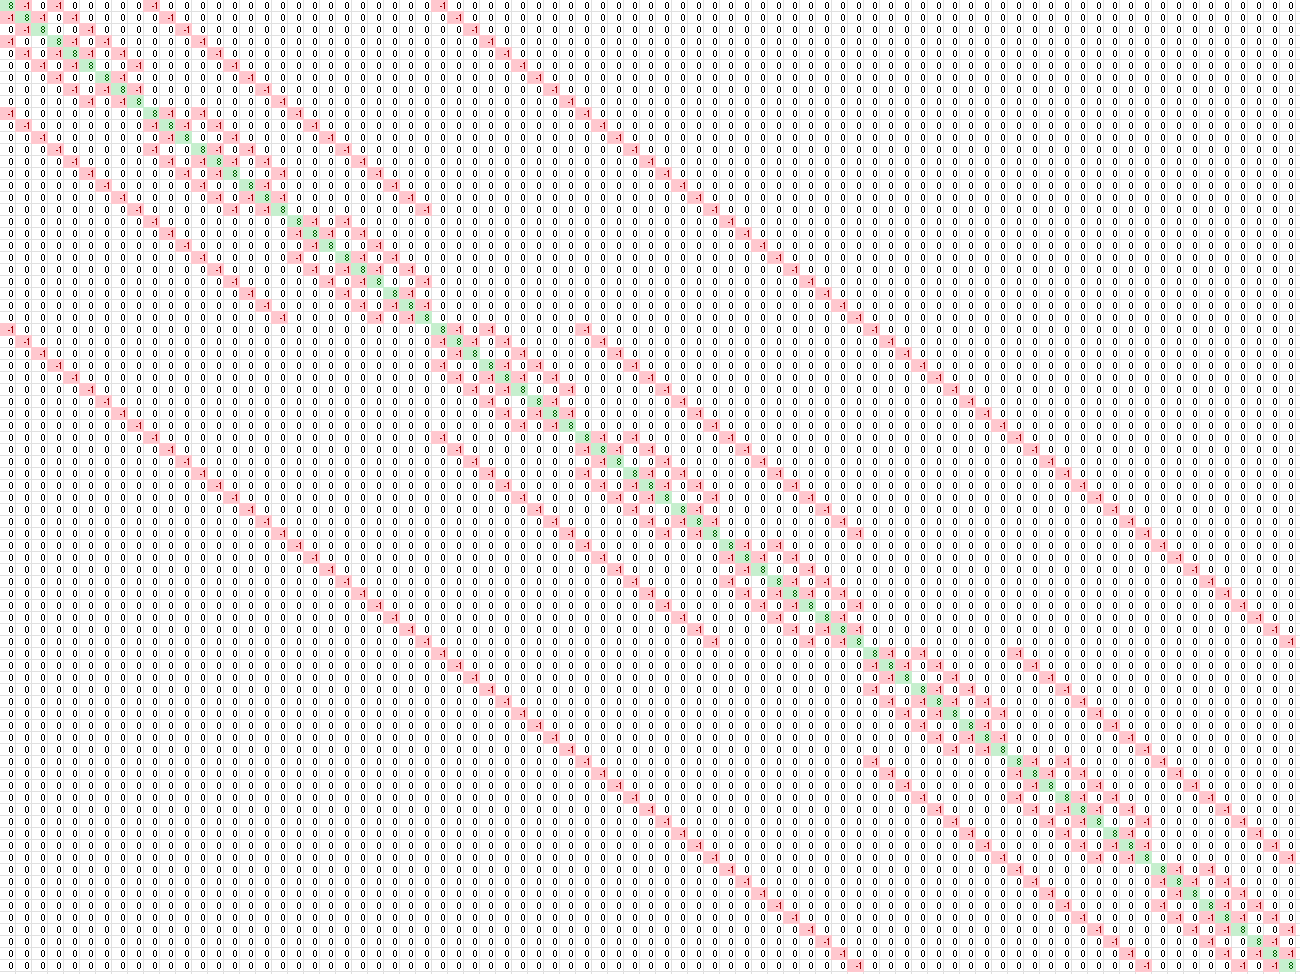

% Sample #5
N = 4;
m = 3;
[ nzA, ir, ic ] = Create_mdiml_Poisson_problem_nzA( N, m );
A = Generate_A_From_CRS( nzA, ir, ic );
writematrix( A, "data_N" + N + "_m" + m + ".csv" );

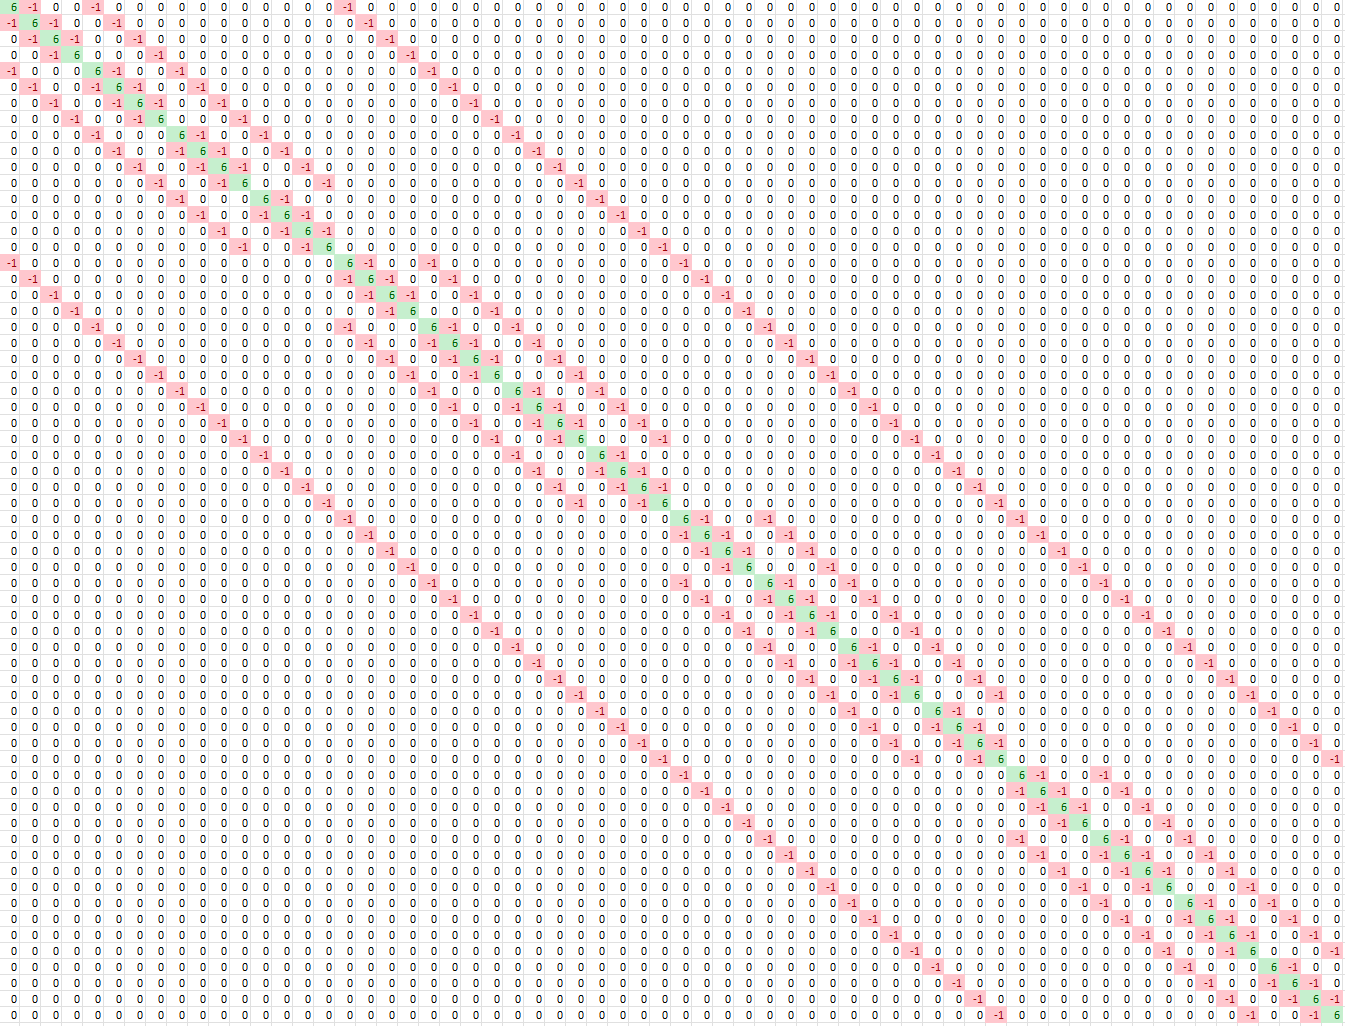

% Sample #6
N = 4;
m = 4;
[ nzA, ir, ic ] = Create_mdiml_Poisson_problem_nzA( N, m );
A = Generate_A_From_CRS( nzA, ir, ic );
writematrix( A, "data_N" + N + "_m" + m + ".csv" );

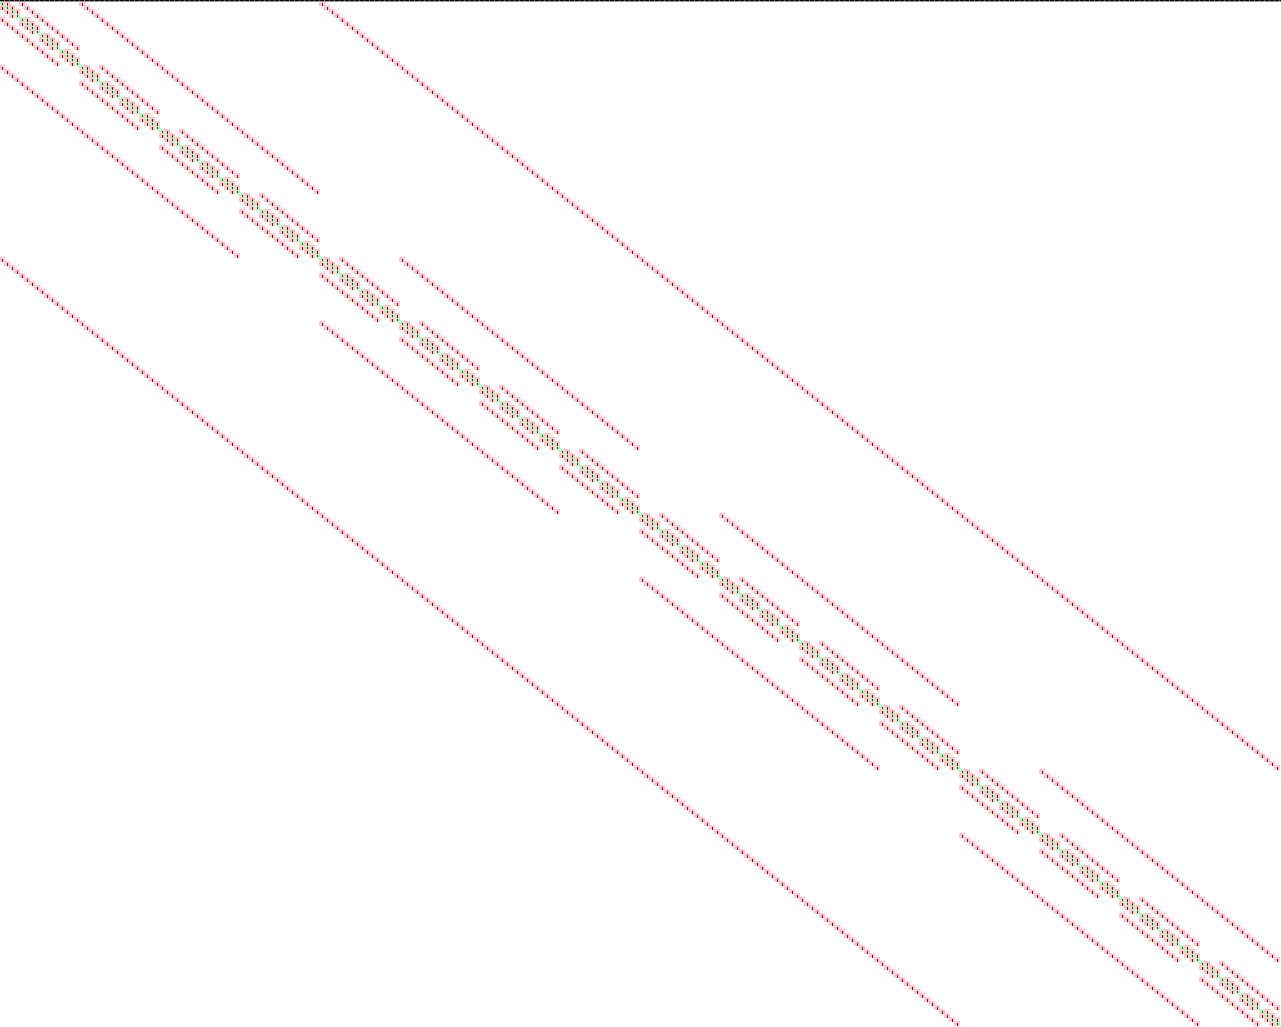

## Question 2 - Method of Steepest Descent Response

Note: Test with Poisson Matrix A from Hwk 8

Using a random exact solution and observing the number of iterations (niters) and the MSD x-vector results.

N = 2;
[ nzA, ir, ic ] = Create_Poisson_problem_nzA( N );
A = Generate_A_From_CRS( nzA, ir, ic );
x_solution = randi( [ 1, 10], N^2, 1);
b = A * x_solution;
% Start with a zero vector.
x0 = zeros( N^2, 1 );
[ msd_x, msd_niters ] = Method_of_Steepest_Descent( A, b, x0 )

msd_x =     9.0000
    4.0000
    7.0000
    2.0000


msd_niters = 33

x_solution

x_solution =      9
     4
     7
     2


% Start with a random guess / vector.
x0 = randi( [ 1, 10 ], N^2, 1 )

x0 =      1
     8
     6
     5


[ msd_x, msd_niters ] = Method_of_Steepest_Descent( A, b, x0 )

msd_x =     9.0000
    4.0000
    7.0000
    2.0000


msd_niters = 50

x_solution

x_solution =      9
     4
     7
     2


msd_x and x_solution are the same.

Using a random b without knonwing the solution x and observing the number of iterations (niters).  Recalculate b with the x from MSD.

b = randi([1,10], N^2, 1);
% Start with a zero vector.
x0 = zeros( N^2, 1 );
[ msd_x, msd_niters ] = Method_of_Steepest_Descent( A, b, x0 )

msd_x =     4.4583
    3.9167
    3.9167
    4.2083


msd_niters = 48

msd_b = A * msd_x

msd_b =    10.0000
    7.0000
    7.0000
    9.0000


b

b =     10
     7
     7
     9


msd_b and b are the same.

Comparing with GSSOR, MSD is faster than GSSOR.  From hwk7, saw GSSOR converge close to the solution in 150 iterations.

N = 3;
[ h2phi, gssor_u ] = Poisson_GSSOR_iteration( N, 150 );
b = h2phi;
[ nzA, ir, ic ] = Create_Poisson_problem_nzA( N );
A = Generate_A_From_CRS( nzA, ir, ic );
x0 = zeros( N^2, 1 );
[ msd_x, msd_niters ] = Method_of_Steepest_Descent( A, b, x0 );

MSD gets to it less than the number of iterations that GSSOR gets to it with very low margin of error / differences.

fprintf( "MSD Solves for Poisson u in %d iterations", msd_niters );

MSD Solves for Poisson u in 1 iterations

GSSOR_MSD_error = abs(norm( msd_x, 2 ) - norm( gssor_u, 2 ))

GSSOR_MSD_error = 0

## Question 3 - Conjugate Gradient Response

Note: Test with Poisson Matrix A from Hwk 8

Consider using a random exact solution and observe the number of iterations (niters) and the CG x-vector results.

N = 2;
[ nzA, ir, ic ] = Create_Poisson_problem_nzA( N );
A = Generate_A_From_CRS( nzA, ir, ic );
x_solution = randi( [ 1, 10], N^2, 1);
b = A * x_solution;
% Start with a zero vector.
x0 = zeros( N^2, 1 );
[ cg_x, cg_niters ] = CG( A, b, x0 )

cg_x =     9.0000
    6.0000
    2.0000
    3.0000


cg_niters = 3

% Start with a random guess / vector.
x0 = rand( N^2, 1)

x0 =     0.8865
    0.0287
    0.4899
    0.1679


[ cg_x, cg_niters ] = CG( A, b, x0 )

cg_x =     9.8865
    6.0287
    2.4899
    3.1679


cg_niters = 3

x_solution

x_solution =      9
     6
     2
     3


cg_x with 0 vector is the same with x_solution, however with random vector that is close to 0, we see the resulting cg_x to be close, which is most likely a result of the search history needing to be linearly independent from one another.

Using a random b without knowing the solution x and observing the number of iterations (niters).  Recalculate b with the x from CG.

b = randi( [ 1, 10 ], N^2, 1);
% Start with a zero vector.
x0 = zeros( N^2, 1 );
[ cg_x, cg_niters ] = CG( A, b, x0 )

cg_x =     4.2917
    3.8333
    3.3333
    3.0417


cg_niters = 3

cg_b = A * cg_x

cg_b =    10.0000
    8.0000
    6.0000
    5.0000


b

b =     10
     8
     6
     5


cg_b and b are the same.

Comparing with GSSOR, CG is faster than GSSOR.  From hwk7, saw GSSOR converge close to the solution in 150 iterations.

N = 3;
[ h2phi, gssor_u ] = Poisson_GSSOR_iteration( N, 150 );
b = h2phi;
[ nzA, ir, ic ] = Create_Poisson_problem_nzA( N );
A = Generate_A_From_CRS( nzA, ir, ic );
x0 = zeros( N^2, 1 );
[ cg_x, cg_niters ] = CG( A, b, x0 )

cg_x =     1.0473
   -1.4811
    1.0473
    0.0000
   -0.0000
    0.0000
   -1.0473
    1.4811
   -1.0473


cg_niters = 1

CG gets to it less than the number of iterations that GSSOR gets to it with very low margin of error / differences.

fprintf( "CG Solves for Poisson u in %d iterations", cg_niters );

CG Solves for Poisson u in 1 iterations

GSSOR_CG_error = abs(norm( cg_x, 2 ) - norm( gssor_u, 2 ))

GSSOR_CG_error = 0

## Other Functions

This LiveScript calls on other function files residing in the same path.  These are:

- Method_of_Steepest_Descent.m

- CG.m

## LiveScript Local Functions

**Create_Poisson_problem_nzA( N )**

function [ nzA, ir, ic ] = Create_Poisson_problem_nzA( N )
    % assume with Poisson equation you will have at most 5 elements per row
    % (i-N for -1, i-1 for -1, i for 4, i+1 for -1, i+N for -1).
    nzA = zeros( ( N^2 ) * 5, 1);
    ir = zeros( N^2 + 1, 1);
    ic = zeros( ( N^2 ) * 5, 1 );
    
    % Number of rows in A
    a_rows = N^2;

    % Calculate the \tilde{a}_i for A ( N^2 x N^2 )
    for i = 1 : a_rows
        % Set ir(1) = 1
        ir(1) = 1;

        % Calculate the column indices for u_i.
        a_row_column_indices = [ i-N, i-1, i, i+1, i+N ];
        % Ignore column indices outside of 1 and N^2 that occurs with i-N,
        % i-1, i+1, i+N
        nz_indices = find( a_row_column_indices>0 & a_row_column_indices<=N^2 );

        % Use the indices from find() to only use valid nonzero column indices.
        a_row_nz_column_indices = a_row_column_indices( nz_indices(1) : nz_indices(end) );
        
        % Calculate the mod / remainder division to determine whether the
        % row you're in sits on a side boundary or not.
        edge = mod( i, N );

        % Remove the i-1 or i+1 that conceptually sits on the side mesh
        % boundaries.
        if edge == 0 && i ~= 1
            a_row_nz_column_indices( a_row_nz_column_indices == i + 1 ) = [];
        elseif edge == 1 && i ~= N^2
            a_row_nz_column_indices( a_row_nz_column_indices == i - 1 ) = [];
        end
        
        % Construct the row values of -1 and 4 based on the current i
        % (row) iteration, where column_indices == i is 4 and everything
        % else is -1.
        a_row_values = a_row_nz_column_indices;
        a_row_values ( a_row_values ~= i ) = -1;
        a_row_values ( a_row_values == i ) = 4;
        
        %i  % debug
        %a_row_nz_column_indices  % debug
        %a_row_values  % debug

        % Set ir( i + 1 ) based on the number of elements in the current
        % row + ir( i ).  Also set ic and nzA.
        ir( i + 1 ) = ir( i ) + length( a_row_values );
        start_indx = ir( i );
        end_indx = ir( i + 1 ) - 1;
        ic( start_indx : end_indx ) = a_row_nz_column_indices;
        nzA( start_indx : end_indx ) = a_row_values;

        % Compress the oversized ic and nzA arrays.
        if i == a_rows
            ic = ic( 1 : ir(end) - 1 );
            nzA = nzA( 1 : ir(end) - 1 );
        end
    end
end

**Test Create_Poisson_problem_nzA()**

function A = Generate_A_From_CRS( nzA, ir, ic )
    a_rows = length(ir) - 1;
    A = zeros( a_rows, a_rows );
    
    for row = 1: a_rows
        col_end_indx = ir( row + 1 ) - 1;
        for col_indx = ir( row ): col_end_indx
            A( row, ic( col_indx ) ) = nzA( col_indx );
        end
    end
end

function Show_nzA_to_A( N )
    [ nzA, ir, ic ] = Create_Poisson_problem_nzA( N );

    A = Generate_A_From_CRS( nzA, ir, ic );
    fprintf( 'A: %d x %d \n', N^2, N^2 );
    disp(A);
end

**Poisson_GSSOR_iteration**

function [ h2phi, u ] = Poisson_GSSOR_iteration( N, nk )
    % Set number of iterations to be performed
    %nk = 500;
    
    % Set parameters alpha and beta
    alpha = 2;
    beta  = 3;
    
    % Set the number of meshpoints so the interior has N x N such points
    %N = 5;
    
    % Compute the distance between mesh points, in each direction
    h = 1/(N+1);
    
    % We will have arrays that capture the boundary as well as the interior
    % meshpoints.  As a result, we need those arrays to be of size (N+2) x
    % (N+2) so that those indexed 2:N+1, 2:N+1 represent the interior.  
    
    % Compute the x-values at each point i,j, including the boundary
    x = h * [ 0:N+1 ];   % Notice this creates a row vector
    
    % Compute the y-values at each point i,j, including the boundary
    y = h * [ 0:N+1 ];   % Notice this creates a row vector
    
    % Create an array that captures the load at each point i,j
    for i=1:N+2
        for j=1:N+2
            F( i,j ) = ...
                ( alpha^2 + beta^2 ) * pi^2 * sin( alpha * pi ...
                * x( i ) ) * sin( beta * pi * y( j ) );
        end
    end

    temp_F = F( 2 : N + 1, 2 : N + 1 );
    H2PHI = temp_F.' * h^2;
    h2phi = reshape(H2PHI,[],1);
    
    % Set the initial values at the mesh points
    U = zeros( N+2, N+2 );
    
    % [ecc567] Set weight for SOR.  Recommended weight given by blogger Isaac
    % from crunchingnumbers.live: (https://crunchingnumbers.live/2017/07/09/iterative-methods-part-2/)
    omega = 2 / (1 + sin(h*pi));
    
    % Perform nk iterations
    for k = 1:nk
        
        % update all the interior points
        for i=2:N+1
            for j=2:N+1
                % Modified core algorithm logic with omega
                U( i,j ) = (1 - omega) * U( i, j ) + ( omega * ...
                ( U( i, j-1 ) + U( i-1, j ) + U( i+1, j ) + ...
                U( i, j+1 ) + h^2 * F( i, j ) ) / 4);
            end
        end 
    end

    temp_U = U( 2 : N + 1, 2 : N + 1 );
    temp_U = temp_U.';
    u = reshape(temp_U,[],1);
end